% This code is to play with one signal at a time, see the error and firing
% rate using the proposed method


load('chirp_signal.mat', 'fd', 'td'); % Load the existing signal vector and time vector
disp('Loaded existing signal vector from generated_signal.mat');

Loaded existing signal vector from generated_signal.mat



Fm = 100;
BW = 2*pi*Fm;
c1 = 1;
alpha = 0.5;
kappa = 5600;
shift = 4.2*c;

[tn, time_stamps, f_n, loc, NoF] = sampling_running_func(fd, td, alpha, kappa, Fm, c1, shift);

disp(['Number of Firings: ', num2str(NoF)]);

Number of Firings: 169


NoF=length(time_stamps)-1;

iter=15;
F_est = reconstruction_running_func(NoF, td, f_n-shift, time_stamps, loc, tn, BW, Fm, iter);

%10 * log10( norm(fd(30000:end-30000) - F_est(30000:end-30000,iter))^2 / norm(fd(30000:end-30000)).^2 )
10 * log10( norm(fd(50000:end-50000) - F_est(50000:end-50000,iter))^2 / norm(fd(50000:end-50000)).^2 )

ans = -53.9605

disp(['Length of td: ', num2str(length(td))]);

Length of td: 900001


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 900001


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [900001 15]


disp(['iter: ', num2str(iter)]);

iter: 15


c1 = 1; c = c1;
% === Normalize the signal ===
normalized_fd = (fd ) / c;

% === Compute firing rate (density) as inverse of inter-spike intervals ===
firing_density = 1 ./ time_stamps;                % Instantaneous firing rate
firing_time = (tn(1:end-1) + tn(2:end)) / 2;  % Midpoints for firing

% === Compute derivative and related quantities ===
signal_derivative = gradient(normalized_fd, td);        
mod_signal_derivative = abs(signal_derivative);         
product_term = normalized_fd .* mod_signal_derivative;  

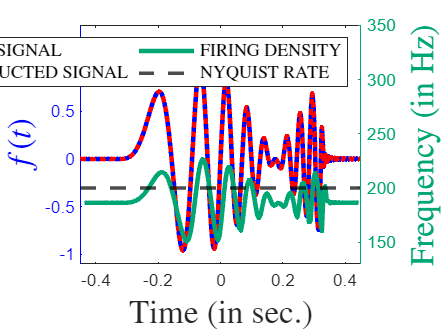


%% === Plot 1: Normalized Signal and Firing Density ===
figure;

% --- Left y-axis: Signal ---
yyaxis left
plot(td, normalized_fd, 'b', 'LineWidth', 2.5, 'DisplayName', 'ORIGINAL SIGNAL'); hold on;
plot(td, F_est(:,iter)/c1, 'r:', 'DisplayName', 'RECONSTRUCTED SIGNAL', 'LineWidth', 2.5); 
ylabel('$f(t)$', 'Interpreter', 'latex', 'FontSize', 18);

% Set left axis color to blue
ax = gca;
ax.YAxis(1).Color = [0 0 1];   % Blue

% --- Right y-axis: Firing Density ---
yyaxis right
plot(firing_time(2:end), firing_density(2:end-2),'Color', '[0 0.65 0.45]', 'LineWidth', 2.5, ...
    'DisplayName', 'FIRING DENSITY');
yline(200, 'k--', 'LineWidth', 2, 'DisplayName', 'NYQUIST RATE');
ylabel('Frequency (in Hz)', 'Interpreter', 'latex', 'FontSize', 18);

% Set right axis color to magenta
ax.YAxis(2).Color = [0 0.65 0.45];   % Magenta

% --- Common axes formatting ---
yyaxis right
ylim([130, 350]);
yyaxis left
ylim([-1.1, 1.4]);

% --- Legend ---
legend('show', 'Interpreter', 'latex', 'FontSize', 10, 'Location', 'northeast', 'NumColumns', 2);

xlabel('Time (in sec.)', 'Interpreter', 'latex', 'FontSize', 18);
xlim([-0.45, 0.45]);

%set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.02))

% exportgraphics(gcf, 'compact_running.pdf', ...
%     'ContentType', 'vector', ...
%     'BackgroundColor', 'none', ...
%     'Resolution', 300);

